# Exercicis

#### Exercici 1

r = sqrt(1-2/pi^5)

r = 0.9967

r = exp(1)^2*log(5)

r = 11.8922

r = sin(2)^2 + cos(4)^2

r = 1.2541

# Booleans

b = (5 >= 5.5)

b = logical
   0


b = (sin(pi) == 0)

b = logical
   0


b = ((7 <= 8) == (3/2 == 1))

b = logical
   0


# Aritmètica de Matlab

a = 4/3

a = 1.3333

b = a - 1

b = 0.3333

c = b + b + b

c = 1.0000

e = 1 - c

e = 2.2204e-16

1 == 1 + eps/2

ans = logical
   1


eps

ans = 2.2204e-16

# Gràfic

x = 0.988:.0001:1.012;
y2 = x.^7-7*x.^6+21*x.^5-35*x.^4+35*x.^3-21*x.^2+7*x-1;
y = (x-1).^7;
coef = [1 -7 21 -35 35 -21 7 -1];
horner(coef,1)

ans = 0

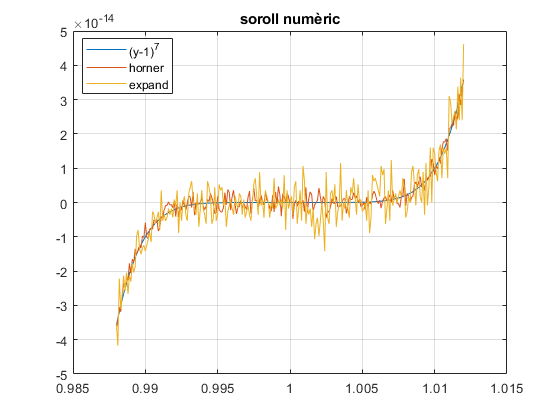

y3 = horner(coef,x);
plot(x,y,x,y3,x,y2)
grid
title('soroll numèric')
legend('(y-1)^7','horner','expand','Location','best')

Regla de Horner

(x^2 - 2*x + 1) = 1 + x*(2-x)

function y = horner(c,x)
% HORNER   Evaluate a polynomial using Horner's rule. 
% Input:
%   c     Coefficients of polynomial, in descending order (vector)
%   x     Evaluation point (scalar)
% Output:
%   y     Value of the polynomial at x (scalar)
n = length(c);
y = c(1);
    for k = 2:n
        y = x.*y + c(k);
    end
end
% from Matlab exchange